# Diseño de controlador PD para mecanismo de dos eslabones

Se realizó un paso para caracterizar los motores, de la siguiente manera:

### Motor 1

PWM  = 175   = 62.74%


$$\tau_{m1} = 0.308563  $$


$K_{m1}  = 3.852961
$ ----> con voltaje medio 

num1 = [3.852961057]; 
dem1 = [0.308563 1 0];
Gp1 = tf(num1, dem1)

Gp1 =
 
      3.853
  --------------
  0.3086 s^2 + s
 
Continuous-time transfer function.
Model Properties


Gc1= pidtune(Gp1,'PD')

Gc1 =
 
             
  Kp + Kd * s
             

  with Kp = 2.63, Kd = 0.271
 
Continuous-time PD controller in parallel form.
Model Properties


%pidTuner(Gp1,Gc1)
Kp1 = 2.63; 
Kd1 = 0.271;
s = tf('s');
C1= Kp1+Kd1*s; %tf de motor
z1 = tf('z');
%controlador discretizado
T1 = 1.0000e-04; %tiempo de muestreo 10KHz 
Cd1=c2d(C1,T1,'tustin')

Cd1 =
 
  5423 z - 5417
  -------------
      z + 1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


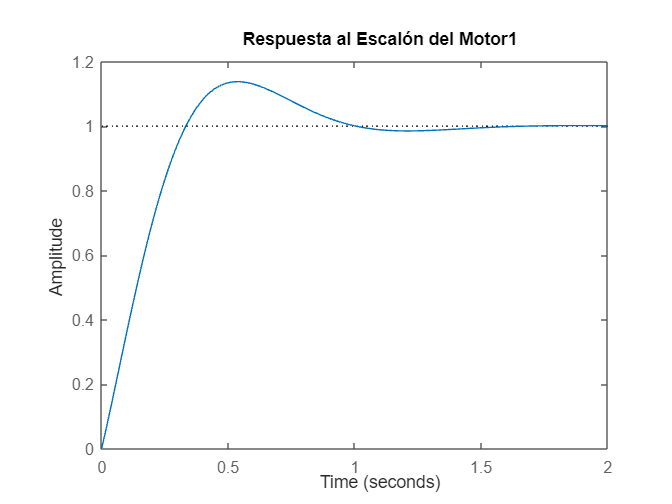

Go1 = feedback (C1*Gp1,1);
figure(1)
step(Go1)
title('Respuesta al Escalón del Motor1');

### Motor 2

PWM  = 35  = 13.72%


$$\tau_{m2} = 0.0955733
  $$


$K_{m2}  =  0.925

$ ----> con voltaje RMS 

num2 = [0.925]; 
dem2 = [0.0955733 1 0];
Gp2 = tf(num2, dem2)

Gp2 =
 
       0.925
  ---------------
  0.09557 s^2 + s
 
Continuous-time transfer function.
Model Properties


Gc2= pidtune(Gp2,'PD')

Gc2 =
 
             
  Kp + Kd * s
             

  with Kp = 35.4, Kd = 1.13
 
Continuous-time PD controller in parallel form.
Model Properties


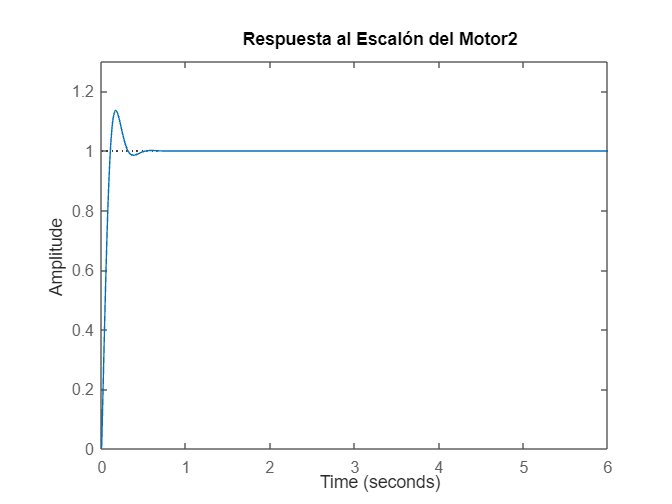

%pidTuner(Gp2,Gc2)
Kp2 = 35;
Kd2 = 1.13;
s = tf('s');
C2= Kp2+Kd2*s; %tf de motor
Go2 = feedback(C2*Gp2,1);
figure(2)
step(Go2);
title('Respuesta al Escalón del Motor2');
ylim([0 1.3])
xlim([0 6])

%controlador discretizado
T2 = 1.0000e-04; %tiempo de muestreo 10KHz 
Cd2=c2d(C2,T2,'tustin')

Cd2 =
 
  22635 z - 2.256e04
  ------------------
        z + 1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties
